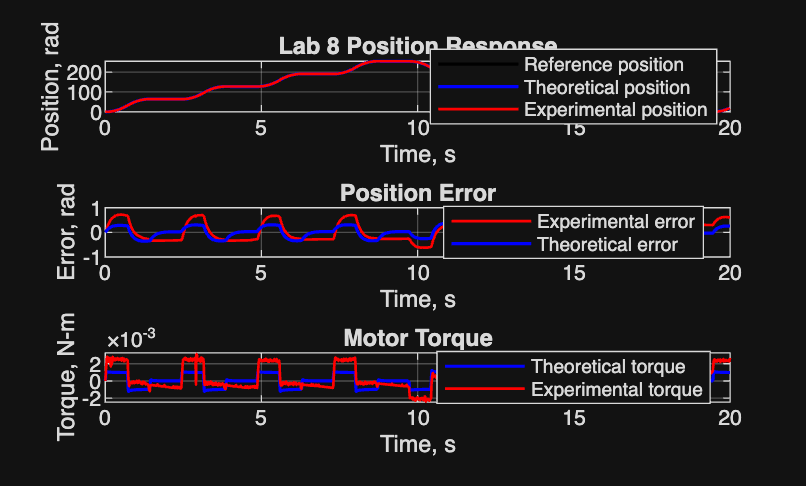

%% Lab 8 Analysis Script
% This script loads Lab8.mat, rebuilds the discrete plant and controller,
% simulates theoretical position and torque responses, and compares them
% to the experimental data.

clear;
clc;
close all;

%% 1. Load experimental data

load Lab8.mat

% Make sure data are column vectors
Pref = Pref(:);      % reference position, rad
Pact = Pact(:);      % experimental position, rad
Vout = Vout(:);      % experimental output voltage, V

% Rename sample time so T is not confused with torque
Ts = T(1);

% Time vector
N = length(Pref);
t = (0:N-1)' * Ts;

%% 2. Define continuous motor/load plant from Lab 7

% T1a parameters
Ka = 0.06;           % amplifier gain, A/V
Km = 0.0698;         % torque constant, N-m/A
J  = 7.8e-6;         % inertia, kg-m^2
B  = 0.0;            % damping, N-m-s/rad

% Voltage-to-position plant:
%
%              Ka*Km
% G(s) = ------------------
%        J*s^2 + B*s
%
% input: amplifier command voltage, V
% output: position, rad

Gs = tf(Ka*Km, [J B 0]);

%% 3. Convert plant to discrete time

Gz = c2d(Gs, Ts, 'zoh');

%% 4. Rebuild discrete controller from PIDF array

% PIDF was saved from C by casting the struct biquad array to double.
% Each biquad section has 11 doubles:
%
% b0 b1 b2 a0 a1 a2 x0 x1 x2 y1 y2
%
% Only the first six are coefficients.

PIDF = PIDF(:);

nsec = length(PIDF) / 11;

if abs(nsec - round(nsec)) > 0
    error('PIDF array length is not a multiple of 11.');
end

nsec = round(nsec);

sections = reshape(PIDF, 11, nsec).';

Cz = tf(1, 1, Ts);

for k = 1:nsec
    b = sections(k, 1:3);
    a = sections(k, 4:6);

    Cz = Cz * tf(b, a, Ts);
end

%% 5. Form closed-loop systems

% Position model:
%
% G1(z) = Theta_J(z) / Theta_R(z)
%       = C(z)G(z) / (1 + C(z)G(z))

G1 = feedback(Cz * Gz, 1);

% Control-voltage model:
%
% U(z) / Theta_R(z) = C(z) / (1 + C(z)G(z))

G_u = feedback(Cz, Gz);

% Torque model:
%
% torque = Ka * Km * Vout
%
% G2(z) = Torque(z) / Theta_R(z)

G2 = (Ka * Km) * G_u;

%% 6. Simulate theoretical responses

Pact_theory = lsim(G1, Pref, t);

Torque_theory = lsim(G2, Pref, t);

%% 7. Compute experimental torque and errors

Torque_exp = Ka * Km * Vout;

Error_exp = Pref - Pact;
Error_theory = Pref - Pact_theory;

%% 8. Plot results

figure;

subplot(3,1,1)
plot(t, Pref, 'k', 'LineWidth', 1.2);
hold on;
plot(t, Pact_theory, 'b', 'LineWidth', 1.2);
plot(t, Pact, 'r', 'LineWidth', 1.0);
grid on;
xlabel('Time, s');
ylabel('Position, rad');
title('Lab 8 Position Response');
legend('Reference position', ...
       'Theoretical position', ...
       'Experimental position', ...
       'Location', 'best');

subplot(3,1,2)
plot(t, Error_exp, 'r', 'LineWidth', 1.0);
hold on;
plot(t, Error_theory, 'b', 'LineWidth', 1.2);
grid on;
xlabel('Time, s');
ylabel('Error, rad');
title('Position Error');
legend('Experimental error', ...
       'Theoretical error', ...
       'Location', 'best');

subplot(3,1,3)
plot(t, Torque_theory, 'b', 'LineWidth', 1.2);
hold on;
plot(t, Torque_exp, 'r', 'LineWidth', 1.0);
grid on;
xlabel('Time, s');
ylabel('Torque, N-m');
title('Motor Torque');
legend('Theoretical torque', ...
       'Experimental torque', ...
       'Location', 'best');


%% 9. Optional checks

disp('Loaded variables:')

Loaded variables:


whos

  Name                  Size            Bytes  Class     Attributes

  B                     1x1                 8  double              
  Cz                    1x1              1278  tf                  
  Error_exp          4000x1             32000  double              
  Error_theory       4000x1             32000  double              
  G1                    1x1              1310  tf                  
  G2                    1x1              1310  tf                  
  G_u                   1x1              1310  tf                  
  Gs                    1x1              1278  tf                  
  Gz                    1x1              1278  tf                  
  J                     1x1                 8  double              
  Ka                    1x1                 8  double              
  Km                    1x1                 8  double              
  N                     1x1                 8  double              
  PIDF                 11x1                88  


disp('Discrete controller Cz:')

Discrete controller Cz:


Cz


Cz =
 
  15.05 z^2 - 29.67 z + 14.62
  ---------------------------
    z^2 - 1.403 z + 0.4034
 
Sample time: 0.005 seconds
Discrete-time transfer function.



disp('Discrete plant Gz:')

Discrete plant Gz:


Gz


Gz =
 
  0.006712 z + 0.006712
  ---------------------
      z^2 - 2 z + 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.



disp('Closed-loop position model G1:')

Closed-loop position model G1:


G1


G1 =
 
   0.101 z^3 - 0.09813 z^2 - 0.101 z + 0.09814
  ----------------------------------------------
  z^4 - 3.302 z^3 + 4.112 z^2 - 2.311 z + 0.5015
 
Sample time: 0.005 seconds
Discrete-time transfer function.



disp('Closed-loop torque model G2:')

Closed-loop torque model G2:


G2


G2 =
 
  0.06302 z^4 - 0.2503 z^3 + 0.3728 z^2 - 0.2467 z + 0.06124
  ----------------------------------------------------------
        z^4 - 3.302 z^3 + 4.112 z^2 - 2.311 z + 0.5015
 
Sample time: 0.005 seconds
Discrete-time transfer function.
